# Distributions of constant and sinusoidal contributions to first principal component

This live MATLAB script reproduces Fig. 3 from Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms of bovine spermatozoa. R. Soc. Open Sci. 7: 200769. 

The first principle component $c_{1\;}$is decomposed into a constant component $\alpha \;$and and a sinusoidal component $\beta \;$as 

    $c_1 =\alpha \;+\beta \;\mathrm{cos}\left(kt-\phi \;\right)$,

where the wavenumber $k$ and the phase $\phi \;$come from a nonlinear fit to the coefficients of all sperm in the dataset. This live script plots histograms of $\alpha \;$and $\beta \;$.

When two samples are compared, the probabiliy that the samples in question are drawn from the same probability distribution (i.e. the p-value of the Kolmogorov-Smirnov test) is also displayed.



addpath('Data',  'Functions',  'Images',  'Movies')
load cell_coeffs.mat
load masks.mat
total_num = size(cell_coeff,2);
Const = zeros(total_num,1);
Cosine = zeros(total_num,1);
% The wavenumber and phase come from a nonlinear fit of the mean of all cell_coeff(:,:,1).
ft = fittype( {'1', '(cos(0.8901*x-2.574))'}, 'independent', 'x', 'dependent', 'y', 'coefficients', {'a', 'b'} );
ts = (1:100)' * (2*pi/100);
% Fit model to data.
for i = 1 : total_num
	f = fit(ts, cell_coeff(:,i), ft);
	Const(i) = f.a;
	Cosine(i) = f.b;
end


bleb_const = B_const(find(bleb_mask == 1) - 79);
unbleb_const = B_const(find(unbleb_mask == 1) - 79);
bleb_cosine = B_cosine(find(bleb_mask == 1) - 79);
unbleb_cosine = B_cosine(find(unbleb_mask == 1) - 79);

## Data for individual sperm

For which sperm do you wish to display the constant and sinusoidal contributions to the first principle component? 

[Select an integer from 1 to 216]

spermid = 7;
period = data{spermid}.period; 
arclength = data{spermid}.flagellum_length;


% Fit model to data.
% for i = spermid
% 	f = fit(ts, cell_coeff(:,i), ft);
% 	Const = f.a;
% 	Cosine = f.b;
% end

disp(['alpha = ' num2str(Const(spermid))]);

alpha = -0.11992


disp(['beta = ' num2str(Cosine(spermid))]);

beta = 0.10814


## Histogram of constant component $\alpha \;$

Which sample do you wish to plot?

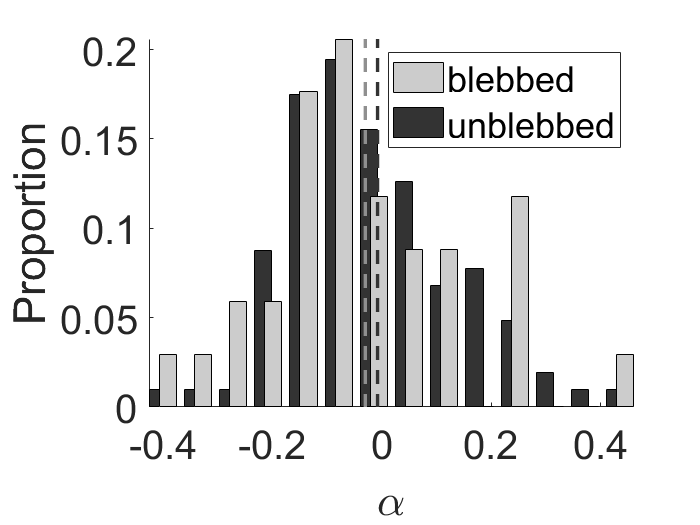

KS p value (const): 0.59313


sample = 6;


if sample == 3
% Make the figure for the A vs B.
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A_const;B_const]);
maxx = max([A_const;B_const]);
edges = linspace(-0.4,0.5,15);
hA = histcounts(A_const,edges,'Normalization','probability');
hB = histcounts(B_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_const),1,2),[0,max([hA,hB])],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
plot(repmat(median(B_const),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\alpha')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'Sample A','Sample B'})
print('alpha.eps','-depsc')


% Const
A_const = Const(A_mask);
B_const = Const(B_mask);
[h,p] = kstest2(A_const,B_const);
disp(['KS p value (const): ' num2str(p)])

elseif sample == 1
    figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A_const]);
maxx = max([A_const]);
edges = linspace(-0.4,0.5,15);
hA = histcounts(A_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_const),1,2),[0,max([hA])],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
xlabel('\alpha')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample A'})
print('alpha.eps','-depsc')


elseif sample == 2
    
    figure
hold on
B_col = 0.2;
minx = min([B_const]);
maxx = max([B_const]);
edges = linspace(-0.4,0.5,15);
hB = histcounts(B_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_const),1,2),[0,max([hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\alpha')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],'Sample B')
print('alpha.eps','-depsc')

elseif sample == 6
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_const;unbleb_const]);
maxx = max([bleb_const;unbleb_const]);
edges = linspace(-0.4,0.5,15);
hA = histcounts(bleb_const,edges,'Normalization','probability');
hB = histcounts(unbleb_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_const),1,2),[0,max([hA,hB])],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_const),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\alpha')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'blebbed','unblebbed'})
print('alpha.eps','-depsc')


% Const
bleb_const = Const(bleb_mask);
unbleb_const = Const(unbleb_mask);
[h,p] = kstest2(bleb_const,unbleb_const);
disp(['KS p value (const): ' num2str(p)])

elseif sample == 4
    figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_const]);
maxx = max([bleb_const]);
edges = linspace(-0.4,0.5,15);
hA = histcounts(bleb_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_const),1,2),[0,max([hA])],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
xlabel('\alpha')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'blebbed'})
print('alpha.eps','-depsc')


elseif sample == 5
    
    figure
hold on
B_col = 0.2;
minx = min([unbleb_const]);
maxx = max([unbleb_const]);
edges = linspace(-0.4,0.5,15);
hB = histcounts(unbleb_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_const),1,2),[0,max([hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\alpha')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'unblebbed'})
print('alpha.eps','-depsc')


end

## Histogram of sinusoidal component $\beta \;\;$

Which sample do you wish to plot?

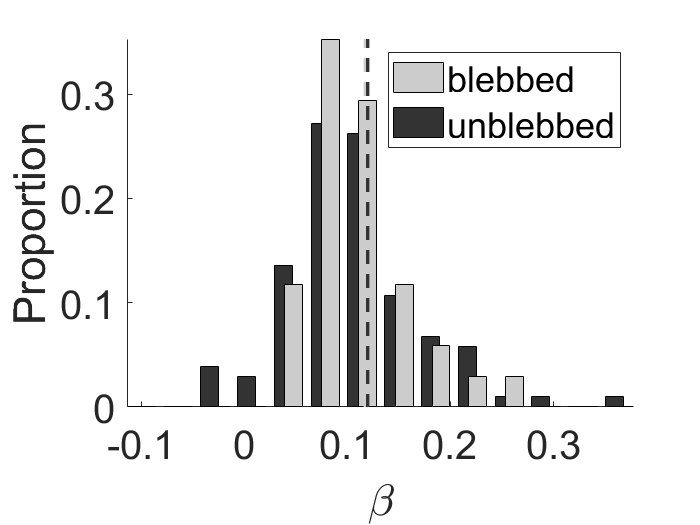

KS p value (cosine): 0.61799


sample = 6;

if sample == 3
figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([A_cosine;B_cosine]);
maxx = max([A_cosine;B_cosine]);
edges = linspace(-0.1,0.4,15);
hA = histcounts(A_cosine,edges,'Normalization','probability');
hB = histcounts(B_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_cosine),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_cosine),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\beta')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'Sample A','Sample B'})
print('beta.eps','-depsc')

% Cosine
A_cosine = Cosine(A_mask);
B_cosine = Cosine(B_mask);
[h,p] = kstest2(A_cosine,B_cosine);

disp(['KS p value (cosine): ',num2str(p)])

disp(' ')

elseif sample == 1
figure
hold on
A_col = 0.8;
minx = min([A_cosine]);
maxx = max([A_cosine]);
edges = linspace(-0.1,0.4,15);
hA = histcounts(A_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_cosine),1,2),[0,max([hA])],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('\beta')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample A'})
print('beta.eps','-depsc')

elseif sample == 2
    figure
hold on
B_col = 0.2;
minx = min([A_cosine;B_cosine]);
maxx = max([A_cosine;B_cosine]);
edges = linspace(-0.1,0.4,15);
hB = histcounts(B_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_cosine),1,2),[0,max([hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\beta')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'Sample B'})
print('beta.eps','-depsc')


elseif sample == 6

figure
hold on
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_cosine;unbleb_cosine]);
maxx = max([bleb_cosine;unbleb_cosine]);
edges = linspace(-0.1,0.4,15);
hA = histcounts(bleb_cosine,edges,'Normalization','probability');
hB = histcounts(unbleb_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_cosine),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_cosine),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\beta')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(2),b(1)],{'blebbed','unblebbed'})
print('beta.eps','-depsc')

% Cosine
bleb_cosine = Cosine(bleb_mask);
unbleb_cosine = Cosine(unbleb_mask);
[h,p] = kstest2(bleb_cosine,unbleb_cosine);



disp(['KS p value (cosine): ',num2str(p)])

elseif sample == 4
figure
hold on
A_col = 0.8;
minx = min([bleb_cosine]);
maxx = max([bleb_cosine]);
edges = linspace(-0.1,0.4,15);
hA = histcounts(bleb_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hA]','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_cosine),1,2),[0,max([hA])],'--','Color',A_col*[1,1,1],'LineWidth',2)
xlabel('\beta')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'blebbed'})
print('beta.eps','-depsc')

elseif sample == 5
    figure
hold on
B_col = 0.2;
minx = min([bleb_cosine;unbleb_cosine]);
maxx = max([bleb_cosine;unbleb_cosine]);
edges = linspace(-0.1,0.4,15);
hB = histcounts(unbleb_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB]','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_cosine),1,2),[0,max([hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
xlabel('\beta')
ylabel('Proportion')
set(gca,'FontSize',24)
axis tight
legend([b(1)],{'unblebbed'})
print('beta.eps','-depsc')
end

% % Bleb vs unbleb
% % Const
% bleb_const = Const(bleb_mask);
% unbleb_const = Const(unbleb_mask);
% [h,p] = kstest2(bleb_const,unbleb_const);
% disp('Bleb vs unbleb')
% disp(['KS p value (const): ',num2str(p)])
% % Cosine
% bleb_cosine = Cosine(bleb_mask);
% unbleb_cosine = Cosine(unbleb_mask);
% [h,p] = kstest2(bleb_cosine,unbleb_cosine);
% disp(['KS p value (cosine): ',num2str(p)])